# 人間の活動のクラスタリング

 これは教師なし学習の例です。 

人間の活動センサー データには、さまざまな活動 (歩く、横になる、座るなど) をしているときに人が装着しているスマートフォンから取得したセンサー測定から得られた観測値が含まれています。 [実験ビデオを視聴します](https://www.youtube.com/watch?v=XOEN9W05_4A) 。 

この分析の目的は、ラベルがない場合に、類似した活動のクラスターとそれらが表す可能性のあるものを識別することです。 ** この教師なし学習の例では、各観測値が対応する活動の種類は事前にわかりません。 **

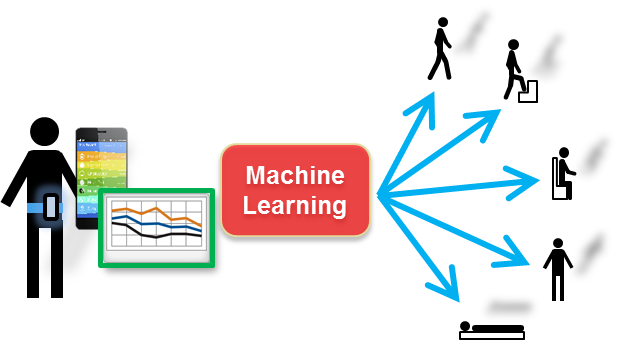

** ハウスキーピング **

ワークスペースをクリアします。 

clear; 

正しいディレクトリにいるかどうかを再確認します。正しい場合は、フォルダーとサブフォルダーをパスに追加します。 

% これを実行して確認します
if isfolder('Additional Files')
    addpath(genpath(pwd))
    disp('You are in the correct directory. Please continue.')
else  
    disp('Please navigate to the proper Directory')
end

You are in the correct directory. Please continue.


## データのロード

6 つの変数 (それぞれが異なるセンサーからの測定値を表す) を含む `rawSensorData` をロードします。 `trainActivity` 変数には、モデルの評価にのみ使用される実際のラベルが含まれています。 

データは、[ホーム] タブにある [データのインポート] ツールを使用してインポートできます。 

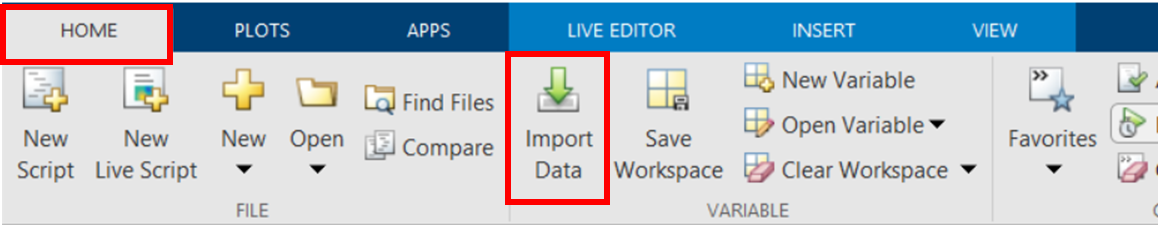

そこで、[追加ファイル] フォルダー (ダブルクリック) と *** rawSensorData_train.mat ファイル ([開く] をクリックするかダブルクリック) を選択します。デフォルトではすべての変数が選択されているので、[完了] を押します。 ***

注: デスクトップ MATLAB® では、下部のボックス (MATLAB コードの生成) をオンにすることで、このアクティビティのコードを生成できます。MATLAB Online では、* コマンド ウィンドウ * にコードが表示されます。 

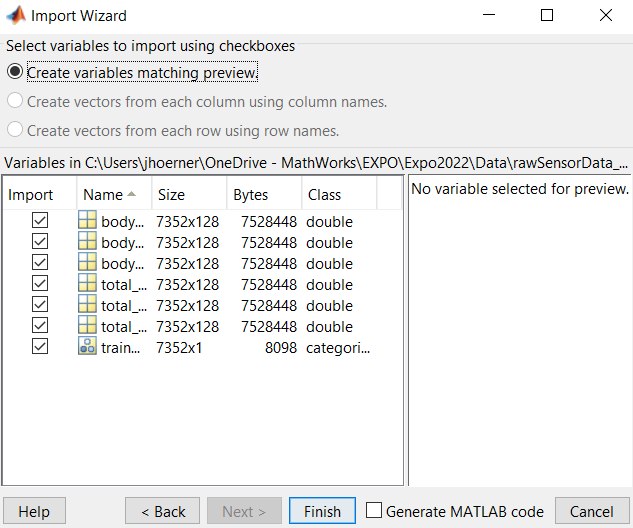

ワークスペースに 7 つの変数が表示されます。 

各行は 1 つの観測値 (128 のデータ ポイント = 128 列) を表します。「類似」行をグループ化してクラスターを見つけます。これは、出力データ (ラベル) がない場合でも、データ セットの意味を理解するのに役立ちます。 

## データの前処理

個々のデータ ポイントが大量にあるため、アクティビティをグループ化することは困難です。このため、平均値と標準偏差を計算して、各観測のデータ ポイント数を減らします。これは次元削減と見ることができます。 

まず、 [平均](https://uk.mathworks.com/help/matlab/ref/mean.html) と [標準偏差](https://uk.mathworks.com/help/matlab/ref/std.html) を計算して、1 つの配列に入れてみましょう。 

accX_mean = mean(total_acc_x, 2);
accY_mean = mean(total_acc_y, 2);
accZ_mean = mean(total_acc_z, 2);
gyroX_mean = mean(body_gyro_x, 2);
gyroY_mean = mean(body_gyro_y, 2);
gyroZ_mean = mean(body_gyro_z, 2);

accX_std = std(total_acc_x, [], 2);
accY_std = std(total_acc_y, [], 2);
accZ_std = std(total_acc_z, [], 2);
gyroX_std = std(body_gyro_x, [], 2);
gyroY_std = std(body_gyro_y, [], 2);
gyroZ_std = std(body_gyro_z, [], 2);

% 1 つの配列に結合します
ActivityDataTrain = [accX_mean accY_mean accZ_mean accX_std accY_std accZ_std ...
    gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std];

% 変数をクリアします (ワークスペースをクリーンな状態に保つため)
clear accX_mean accY_mean accZ_mean accX_std accY_std accZ_std gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std

## K-Means クラスタリング

[kmeans ドキュメントを開きます](matlab: doc kmeans)

K-Means クラスタリングは、データ セットを K 個の相互に排他的なクラスターまたはグループに分割する方法です。データ内の各観測を、空間内に位置を持つオブジェクトとして扱い、各クラスター内のオブジェクトが可能な限り互いに近く、他のクラスター内のオブジェクトから可能な限り離れているパーティションを見つけます。K-Means は、すべてのクラスターにわたって、各オブジェクトからそのクラスターの重心までの距離の合計を最小化する反復アルゴリズムを使用します。 

** K-Means: **

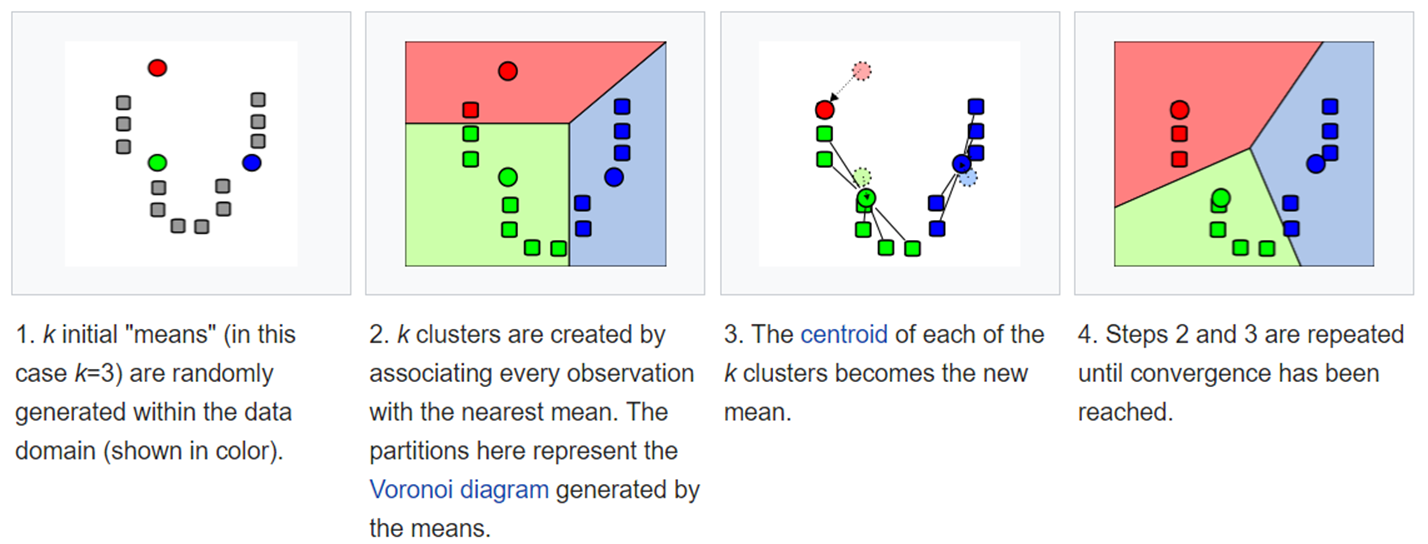

[出典: Wikipedia](https://en.wikipedia.org/wiki/K-means_clustering)

データをクラスター化するために * ライブ タスク * を使用できます。これは、 * タスク * の * ライブ エディター * タブにあります。 * クラスター データ * を選択してください。 

入力データとして配列 `ActivityDataTrain` を選択します。 

クラスターの数を指定できます。ラベルがないと仮定すると、実際のクラス数 (6 クラス: 立っている、座っている、横になっている、歩いている、階段を下りる、階段を上る) を選択するか、より少ない数から始めてパフォーマンスを確認することもできます。 

クラスの数を試して、たとえば 2 クラス (静止、移動) または 3 クラス (静止、横になっている、移動) を選択できます。 

注: 最適なクラスター数を見つけるには、* 選択方法 * を * 最適 * に変更し、クラスター数の範囲と * 評価基準 * を指定します。 

rng('default') % ランダムシードを制御するため、クラスタリングタスクを実行するたびに同じ結果が得られます

% Insert the live task here 

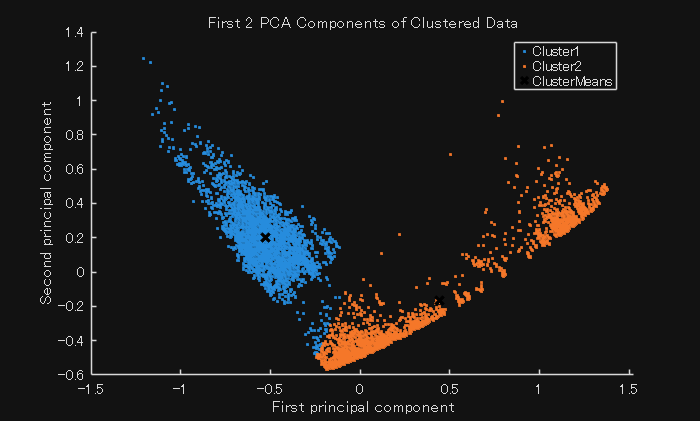

% 指定されたクラスター数 (K 値) を使用して k-means クラスタリングを実行
K = 2;
[clusterIndices,centroids] = kmeans(ActivityDataTrain,K);
clear K

% 結果の表示

% 2D 散布図 (PCA) を表示
figure
[~,score] = pca(ActivityDataTrain);
clusterMeans = grpstats(score,clusterIndices,"mean");
h = gscatter(score(:,1),score(:,2),clusterIndices);
for i = 1:numel(h)
    h(i).DisplayName = strcat("Cluster",h(i).DisplayName);
end
clear h i score
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

## モデルを評価します

アクティビティの実際のラベルがわかっているので、モデルが正しかったかどうかを再確認できます。 

したがって、各クラスターのインデックスを取得し、これらのインデックスのアクティビティを表示します。 

注: このコードは 3 つのクラスターに対して機能します。クラスターの数が多い場合や少ない場合は調整する必要があります。 

idx_cl1 = clusterIndices==1;
idx_cl2 = clusterIndices==2;
idx_cl3 = clusterIndices==3;

act_1 = trainActivity(idx_cl1, :);
act_2 = trainActivity(idx_cl2, :);
act_3 = trainActivity(idx_cl3, :);
summary(act_1); %cluster 1
summary(act_2); %cluster 2
summary(act_3); %cluster 3 

ご覧のとおり、モデルはほとんどのアクティビティを正しいクラスターにグループ化しました。 

## まとめと次の手順

この例では、携帯電話から取得した測定値を同様の特性を持つグループにクラスター化しました。この手法はパターンを見つけるのに役立ちますが、データにラベルを付ける場合にも役立ちます (ラベルが利用できない場合)。 

k-means クラスタリング手法を適用したところ、比較的良好な結果が得られました。[こちら](https://uk.mathworks.com/help/stats/cluster-analysis.html) で説明されている他の方法を試すこともできます。 

* Copyright 2022, The MathWorks, Inc. *